# Cruise control using PI compensation

This livescript is a brief manual in support of the app ***cruisecontrol.mlapp***.   This is a simple interface to practice the role of PI compensation for cruise control where the care is subject to small wind and slope disturbances.

Users may find the app ***carmodel_and_behaviour.mlapp*** on open-loop behaviour useful to look at first.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineering context

- Objective of cruise control

- Closed-loop analysis

- Closed-loop behaviour

- Image and components and animation

- Interface and user interaction

## 1. Engineering context

We consider a car can be represented as a simple mass-damper model, the damping representing friction which is assumed proportional to velocity. So with mass *M*, damping/friction coefficient *B*, *C* the maximum engine force, and throttle position *f*, the model is:


$$M\frac{\textrm{dv}}{\textrm{dt}}+\textrm{Bv}=\textrm{Cf}$$


In practice the road may not be level and have a slope $\theta$. Also there may be wind of speed *w*. These two factors affect the model in the following way.

 $M\frac{\textrm{dv}}{\textrm{dt}}+B\left(v+w\right)+\textrm{Mgsin}\left(\theta \right)=\textrm{Cf}$    [Hereafter assume small angles so $\theta =\sin \left(\theta \right)$.]

Hence, this can be represented as a transfer function model with one output (velocity) and three inputs (throttle, slope, wind).


$$v\left(s\right)=\frac{C}{\textrm{Ms}+B}f\left(s\right)-\frac{\textrm{Mg}}{\textrm{Ms}+B}\theta \left(s\right)-\frac{B}{\textrm{Ms}+B}w\left(s\right)$$


% y = G*u + F*slope + W*wind
M=600; B=200; Kp=0.2;Ki=0.1;
G=tf(1000,[M,B]) % car model

G =
 
     1000
  -----------
  600 s + 200
 
Continuous-time transfer function.



PI=tf([Kp,Ki],[1 0]) % PI compensator

PI =
 
  0.2 s + 0.1
  -----------
       s
 
Continuous-time transfer function.



W=tf(B,[M,B])     % wind to velocity

W =
 
      200
  -----------
  600 s + 200
 
Continuous-time transfer function.



F=tf(M*10,[M,B])  % slope to velocity

F =
 
     6000
  -----------
  600 s + 200
 
Continuous-time transfer function.



## 2. Objective of cruise control

We wish to control the speed *Y* of the car to the target R by moving the throttle. To do this a PI compensator is used :


$$f\left(s\right)=\left(K_p +\frac{K_i }{s}\right)\left(R\left(s\right)-Y\left(s\right)\right)=C\left(s\right)\left(R\left(s\right)-Y\left(s\right)\right)$$


Standard control theory will tell readers that including the integral will ensure offset free tracking in the steady-state, and because the model is first order, stability is assured. However, we still need to determine sensible values for the compensator coefficients.

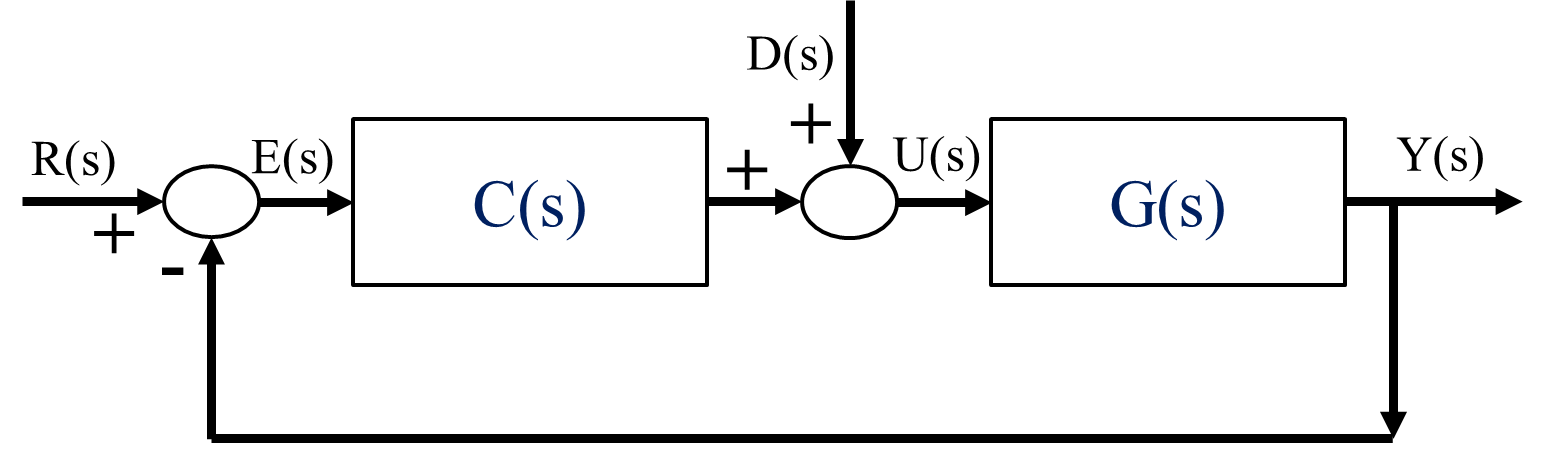

The closed-loop transferences for the block diagram above can be summarised as:

$Y_r \left(s\right)=G_c \left(s\right)H\left(s\right)$ with   $G_c =\frac{\textrm{GC}}{1+\textrm{GC}}$         Dependence of speed on the target.

$U_r \left(s\right)=G_{\textrm{cu}} \left(s\right)H\left(s\right)$ with   $G_{\textrm{cu}} =\frac{C}{1+\textrm{GC}}$    Dependence of throttle on the target.

$Y_d \left(s\right)=G_{\textrm{cd}} \left(s\right)d\left(s\right)$ with   $G_{\textrm{cd}} =\frac{G}{1+\textrm{GC}}$    Dependence of speed on a  disturbance (e.g. change in the slope or wind).

$U_d \left(s\right)=G_{\textrm{cud}} \left(s\right)d\left(s\right)$ with   $G_{\textrm{cud}} =\frac{-\textrm{GC}}{1+\textrm{GC}}$    Dependence of the throttle  on a disturbance..

The total speed and throttle is computed from superposition, hence:


$$h=Y_r +Y_d ;\;\;\;f=U_r +U_d$$


## 3. Closed-loop analysis

The closed-loop transferences for the block diagram above, from the different inputs to the velocity and throttle can be determined using MATLAB. Illustrative code given here.

disp('*******************************************************************')

*******************************************************************


disp('Section 3, 4 code output below: forming closed-loop transfer functions/responses')

Section 3, 4 code output below: forming closed-loop transfer functions/responses


% y = G*u + F*slope + W*wind
% y = GM/(1+GPI)* R -  F/(1+GPI) s -  W/(1+GPI) w
% u = M/(1+GPI) * R  + PIF/(1+GPI) s +  W/(1+GPI) w
M=600; B=200; Kp=0.2;Ki=0.1;
G=tf(1000,[M,B]); % car model
PI=tf([Kp,Ki],[1 0]); % PI compensator
W=tf(B,[M,B]);     % wind to velocity
F=tf(M*10,[M,B]);  % slope to velocity
disp('Closed-loop target to output transfer function')

Closed-loop target to output transfer function


Gcy=feedback(G*PI,1)

Gcy =
 
       200 s + 100
  ---------------------
  600 s^2 + 400 s + 100
 
Continuous-time transfer function.



Gcu=feedback(PI,G);
disp('Closed-loop slope to output transfer function')

Closed-loop slope to output transfer function


Gcdy=-feedback(1,G*PI)*F

Gcdy =
 
            -3.6e06 s^2 - 1.2e06 s
  ------------------------------------------
  360000 s^3 + 360000 s^2 + 140000 s + 20000
 
Continuous-time transfer function.



Gcdu = Gcu*F;
Gcwy=-feedback(1,G*PI)*W;
Gcwu=Gcu*W;

## 4. Closed-loop behaviour

The responses are most easily determined using ***step.m*** and then using superposition to build the total response. For simplicity default run times and targets are used in the app to avoid clutter on the interface. Example code given here for output responses to the target and slope.

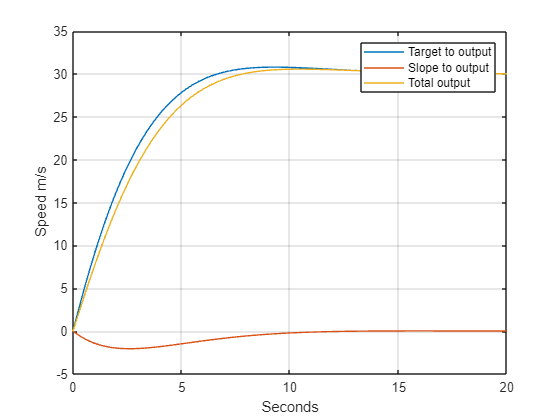

longtimescale=20;targetspeed=30;
time=linspace(0,longtimescale,101);
yr = step(Gcy,time)*targetspeed;
ur = step(Gcu,time)*targetspeed;
ys = step(Gcdy,time)*0.2;
figure
plot(time,yr,time,ys,time,yr+ys); grid
legend('Target to output','Slope to output','Total output')
xlabel('Seconds')
ylabel('Speed m/s')

## 5. Interface and user interaction

The image shows a car going up a slope.

- If wind is activated, this appears in the figure. When wind is assumed negligible, the green arrows vanish.

- The red and green posts are used to represent movement. The red is the car speed and the green moves at the target speed so the user can visualise easily when the car is tracking speed poorly.

- The animation runs for about 10 seconds to show the responses in the current scenario; this includes animation of the line plots.

The user can change only a few parameters as we want to keep the app simple and transparent to use.

- The mass and friction parameters which determine the car model

- The proportional and integral compenents of the compensator.

- Selection of uphill, downhill and wind on or off.

- Step or  square wave targets.

Users cannot select windspeed or slope angle as we did not want to overload the interface. Of course these would be easy to add for users who would like to edit the code themselves.

Users can run the simulation with various choices of parameters and overlay the results so they can build a picture and understanding of the impact of different changes. To refresh and begin again, use the clean figures button.

The animation on/off button can be used to switch off the animation for faster display of the results.